# Note 1

The purpose of this note is to introduce the non-linear differential equation in the simple 1D case. 

The Monge-Ampere which is most generally in the form: 

        
$$L\left\lbrack u\right\rbrack =\mathrm{det}\;D^2 u=f\left(x,u,D\;u\right)$$


is a fully non-linear elliptic PDE for convex $u$. 

## Gaussian Curvature Problem 

Let $u\left(x\right)$ be a surface (or a curve in 1D) over some domain $\Omega \;\ldotp$

Let $\kappa \left(x\right)$ be the Gaussian curvature of $u$ at the point $x\;\mathrm{in}\;\Omega$.

Given $\kappa \left(x\right)$, the prescribed n-dimensional Gaussian curvature problem is to find $u\left(x\right)$ satisfying:

        $\kappa \left(x\right)=\frac{\mathrm{det}\left(D^2 u\left(x\right)\right)}{{\left(1+\left|\nabla u\left(x\right){\left|\right.}^2 \right.\right)}^{\frac{\left(n+2\right)}{2}} }$.

The operator $D^2 u\left(x\right)$ is the Hessian, sometimes denoted by $H=D^2 u,\;{\left(H\right)}_{\mathrm{ij}} =\frac{\partial^2 u}{\partial x_i \partial x_j }$. 

The Gaussian curvature problem is a form of the Monge-Ampere with $f=\;$${\kappa \left(x\right)\left(1+\left|\nabla u\left(x\right){\left|\right.}^2 \right.\right)}^{\frac{\left(n+2\right)}{2}}$.

We will enforce Dirichlet boundary conditions, $u=g\;\mathrm{on}\;\partial \Omega$. 

## 1-D Problem

The 1-D problem version of the GCP is expressed as:

$\left\lbrace \begin{array}{ll}
\ddot{u} \left(x\right)-\kappa \left(x\right){\left(1+\dot{u} {\left(x\right)}^2 \right)}^{\frac{3}{2}} =0 & a<x<b\\
u\left(x\right)=g_a  & x=a\\
u\left(x\right)=g_b  & x=b
\end{array}\right.$.

where $g_a$ and $g_b$ are constants. 

For a simplified case, the problem permits an exact solution. For instance, let the curvature be constant $\kappa =1$, and let $a=0$, $b=1$, $g_a =0$, and $g_b =1$. Then we get an exact solution:

        
$$u_{\mathrm{exact}} \left(x\right)=-\sqrt{1-x^2 }+1$$


The following plot shows the solution. 

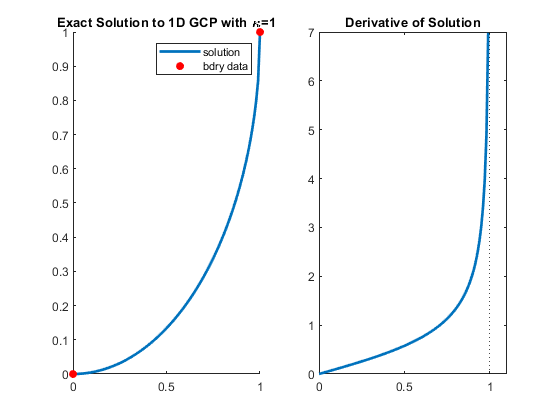

clear

u_exact =@(x) -sqrt(1-x.^2)+1; % exact viscosity solution 
u_deriv =@(x) x./sqrt(1-x.^2);

% parameters:
a = 0;  b = 1;      % domain 
ga = 0;             % u(a) = ga
gb = 1;             % u(b) = gb
x = linspace(a,b);

figure
subplot(121)
hold on
plot(x,u_exact(x),'linewidth',2)
scatter([a,b],[ga gb],'r','filled')
title('Exact Solution to 1D GCP with \kappa=1')
legend('solution','bdry data')
subplot(122)
plot(x,u_deriv(x),'linewidth',2)
xlim([0 1.1])
xline(1,'k:')
title('Derivative of Solution')

The solution is plotted on the left. The solution satisfies the Dirichlet conditions. 

The right plot shows the derivative of the solution which blows up at the right endpoint. 

## Viscosity Solution

There is a problem with this solution at the right bounbary. This solution is $C^2$ in the domain but only $C^0$ up to the boundary. In majority of the circumstances, a clasical solution will not exist. 

The viscosity solution is a  more generalized form of solutions to 2nd order PDEs. There are numerical schemes that are known to converge to viscosity solutions. 

Consider the problem in which does not admit a classical solution:

        $\left\lbrace \begin{array}{ll}
\ddot{u} \left(x\right)-\kappa \left(x\right){\left(1+\dot{u} {\left(x\right)}^2 \right)}^{\frac{3}{2}} =0 & 0<x<1\\
u\left(x\right)=0 & x=0\\
u\left(x\right)=2 & x=1
\end{array}\right.$.

It's impossible for the conditions at the left and right endpoints to be satisfied at the same time. 

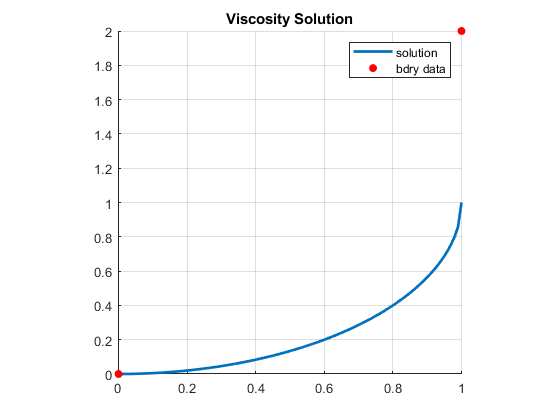

gb = 2;
figure
hold on
plot(x,u_exact(x),'linewidth',2)
scatter([a,b],[ga gb],'r','filled')
axis square, grid on
title('Viscosity Solution')
legend('solution','bdry data')

The classical solution does not exist. However, a viscosity solution does exist. It contains a jump at the right endpoint. 

## Monotonic Discretization Scheme 

We need to utilize a special discrtization scheme that ensures the convexity of the final solution. 

To approximate the solution, we start by breaking the interval $\left(a,b\right)$ into $N$subintervals. For a uniform grid we write $x_i =a+i\;h,$ $i=0,\ldotp \ldotp \ldotp ,N,N+1$ where $h=\frac{\left(b-a\right)}{N+1}$. We need a monotonic discretization of the derivative terms. In the 1D case this amounts to using the following approximations: 


$$\dot{u} \left(x_i \right)\approx \mathrm{max}\left(\frac{u_i -u_{i-1} }{h},-\frac{u_{i+1} -u_i }{\;h},0\right)$$



$$\ddot{u} \left(x_i \right)\approx \frac{u_{i+1} -2u_i +u_{i-1} }{h^2 }$$


We need a montonic scheme to ensure convergence to the viscosity solution. 

## Sample Numerical Solution 

The PDE is nonlinear i.e. even if we use the finite difference scheme, there is no way to contsruct the linear system. We must a root finding scheme. 

Matlab offers tools to solve nonlinear equations. We can construct a function of which we wish to find the root which represents a discretized form of the PDE. Then we use `fsolve` to get the solution. 

Note: `fsolve` is a part of Matlab's Optimization toolbox. 

N = 100;
kap = 1;
h = (b-a)/(N+1);
X = a+h:h:b-h;
U = zeros(size(X));
f =@(u) D(u,ga,gb,h,kap); % the LHS of the PDE 
U = fsolve(f,U); % use nonlinear solver from optimization toolbox


Equation solved, inaccuracy possible.

The vector of function values is near zero, as measured by the value
of the function tolerance. However, the last step was ineffective.

<stopping criteria details>


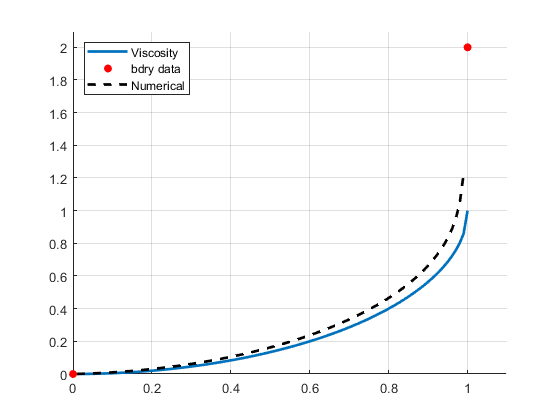

figure
hold on
plot(x,u_exact(x),'linewidth',2)
scatter([a,b],[ga gb],'r','filled')
axis([0,1.1,0,2.1]), grid on
plot(X,U,'k--','linewidth',2)
legend('Viscosity','bdry data','Numerical','location','northwest')

The dotted line shows the numerical solution. As $N\to \infty$, the numerical solution converges to the discrete solution. 

## Functions

The function D is the discrete form of the left hand side of the equation $\ddot{u} \left(x\right)-\kappa \left(x\right){\left(1+\dot{u} {\left(x\right)}^2 \right)}^{\frac{3}{2}} =0$. The input u is supposed to be an unknown vector representing $u_i \approx u\left(x_i \right)$. 

The ga and gb are the boundary data, h is the step size, and kap is the constant curvature. 

We use the function D to create a function handle which takes a single input u. We then use `fsolve` to approximate the root. 

function F = D(u,ga,gb,h,kap)
N = length(u);
F = zeros(N,1);
ih2 = 1/h^2;

F(1) = ih2*(u(2)-2*u(1)+ga)-kap*(1+ih2*max([u(1)-ga,u(1)-u(2),0])^2)^(3/2); % at the left endpoint 

for j = 2:N-1
    F(j) = ih2*(u(j+1)-2*u(j)+u(j-1))-kap*(1+ih2*max([u(j)-u(j-1),u(j)-u(j+1),0])^2)^(3/2); % at the middle points
end

F(N) = ih2*(gb-2*u(N)+u(N-1))-kap*(1+ih2*max([u(N)-u(N-1),u(N)-gb,0])^2)^(3/2); % at the right endpoint

end